Gibbs

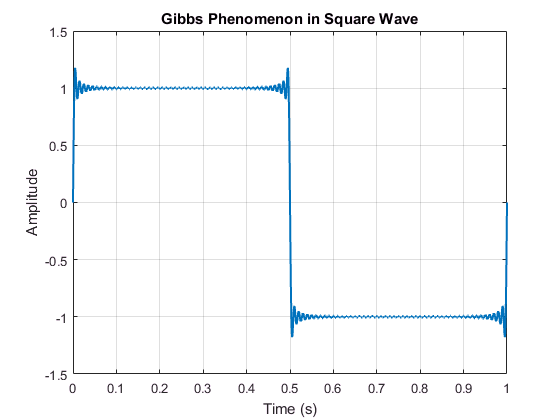

% Define the time vector
t = 0:0.001:1;

% Initialize the Fourier series
f = zeros(size(t));

% Number of terms in the Fourier series
N = 100;

% Fundamental frequency
w0 = 2*pi;

% Construct the Fourier series
for n = 1:2:N
    f = f + (4/pi) * (1/n) * sin(n * w0 * t);
end

% Plot the square wave and its Fourier series approximation
figure;
plot(t, f, 'LineWidth', 1.5);
ylim([-1.5 1.5]);
title('Gibbs Phenomenon in Square Wave');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

FFT

% Define a time vector
t = 0:0.001:1;

% Create a signal with sharp transitions (high differences)
signal = zeros(size(t));
signal(1:500) = 1; % High difference at t=0.5

% Compute the Fourier transform of the signal
Y = fft(signal);

% Calculate the frequency vector
Fs = 1000; % Sampling frequency
f = (0:length(Y)-1)*Fs/length(Y);

% Plot the signal in the time domain
subplot(2,1,1);
plot(t, signal);
title('Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the magnitude of the FFT of the signal
subplot(2,1,2);
plot(f, abs(Y));
title('Magnitude of FFT');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

% Limit the x-axis to show only the first 100 Hz
xlim([0 100]);

STFT

% Define the time vector
t = 0:0.001:1;

% Create a rectangular pulse signal 
signal = zeros(size(t));
signal(450:550) = 1; % Pulse from t=0.45 to t=0.55

% Compute the Fourier transform of the signal
Y = fft(signal);

% Normalize the amplitude of the Fourier transform
Y = Y/length(Y);

% Calculate the frequency vector
Fs = 1000; % Sampling frequency
f = (0:length(Y)-1)*Fs/length(Y);

% Plot the signal in the time domain
subplot(2,1,1);
plot(t, signal, 'LineWidth', 1.5);
title('Rectangular Pulse in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the magnitude of the FFT of the signal
subplot(2,1,2);
plot(f, abs(Y), 'LineWidth', 1.5);
title('Magnitude of FFT');
xlabel('Frequency (Hz)');
ylabel('|Y(f)|');

% Limit the x-axis to show only the first 100 Hz
xlim([0 100]);


sdf

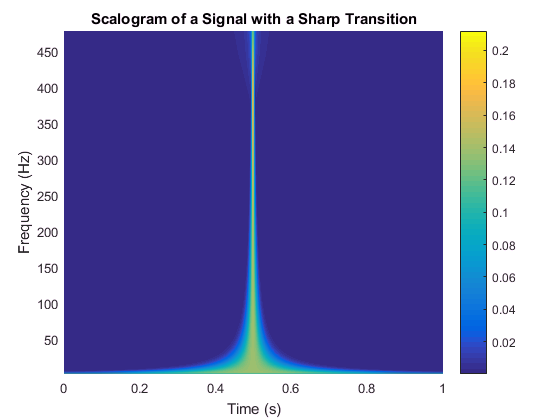

% Define the time vector
t = 0:0.001:1;

% Create a signal with a sharp transition
signal = zeros(size(t));
signal(500:end) = 1; % Sharp transition at t=0.5

% Perform the Continuous Wavelet Transform (CWT)
[wt, f] = cwt(signal, 'amor', 1000);

% Plot the CWT as a scalogram
figure;
pcolor(t, f, abs(wt));
shading interp;
title('Scalogram of a Signal with a Sharp Transition');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
colorbar;

transition from a Fourier series of a periodic signal to the Fourier transform of a non-periodic signal

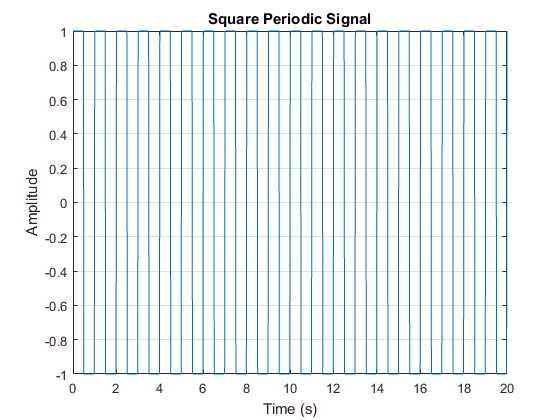


period = 1; % Initial period of the signal
amplitude = 1; % Amplitude of the signal
duration = 20; % Duration of the signal

% Create a square periodic signal
t = linspace(0, duration, 1000); % Time vector
x = square(2*pi*t/period, 50); % Square periodic signal with 50% duty cycle

% Plot the square periodic signal
figure;
plot(t, x);
title('Square Periodic Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

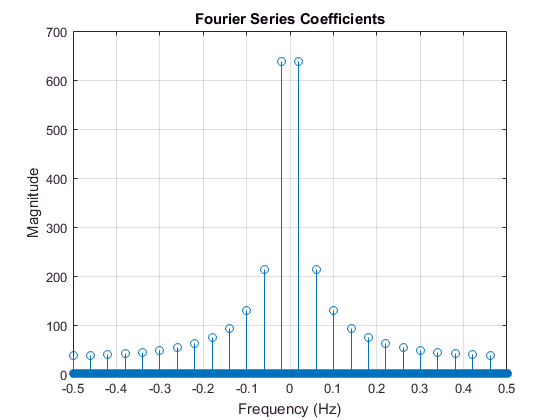


% Compute the Fourier series coefficients
coefficients = fftshift(fft(x)); % Compute the Fourier coefficients
frequencies = linspace(-1/2/period, 1/2/period, length(coefficients)); % Frequency vector

% Plot the Fourier series coefficients
figure;
stem(frequencies, abs(coefficients));
title('Fourier Series Coefficients');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

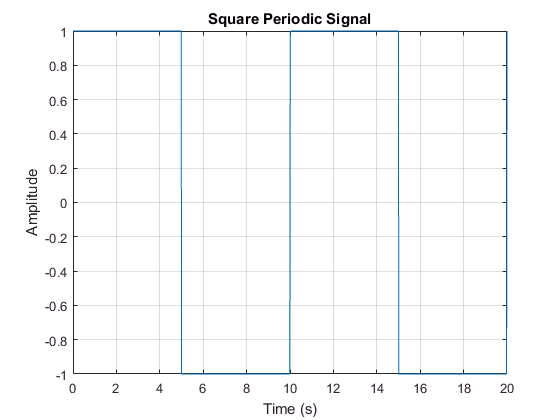


% Change the period of the signal manually
period = 10; % New period

% Update the square periodic signal and its Fourier series coefficients
x = square(2*pi*t/period, 50);
coefficients = fftshift(fft(x));
frequencies = linspace(-1/2/period, 1/2/period, length(coefficients));

% Update the plots
figure(1);
plot(t, x);
title('Square Periodic Signal');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

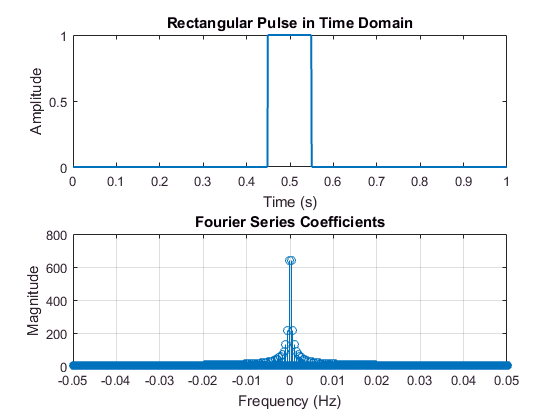


figure(2);
stem(frequencies, abs(coefficients));
title('Fourier Series Coefficients');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

Show Fourier transform amp and phase

% Define the time vector with sampling period Ts
Ts = 0.01; % Sampling period in seconds
t = 0:Ts:100; % Time vector

% Define the parameter 'a'
a = 1; % Example value

% Define the signal x(t)
x_t = exp(-a*t);
% Plot the signal
figure;
plot(t, x_t);
title('Signal x(t)');
xlabel('Time (s)');
ylabel('Amplitude');

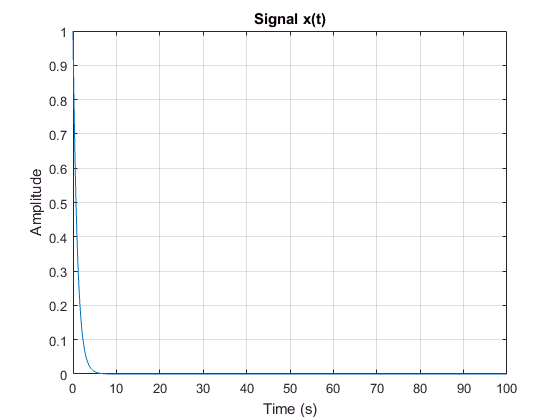

grid on;

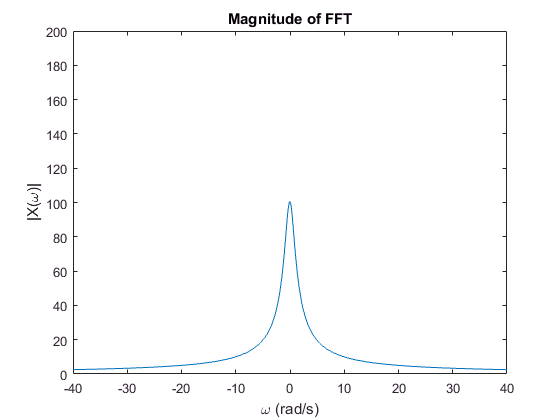



% Compute the FFT of the signal
X_fft = fft(x_t);

% Compute the number of points in FFT
n = length(X_fft);

% Define the angular frequency vector for the FFT output
omega = (-n/2:n/2-1)*(2*pi/(Ts*n)); % Angular frequency vector in rad/s

% Shift the zero frequency component to the center
X_fft_shifted = fftshift(X_fft);

% Calculate the magnitude and phase
X_mag = abs(X_fft_shifted);
X_phase = angle(X_fft_shifted);

% Plot the magnitude of FFT
figure;
plot(omega, X_mag);
title('Magnitude of FFT');
xlabel('\omega (rad/s)');
ylabel('|X(\omega)|');

xlim([-40.0 40.0])
ylim([0 200])

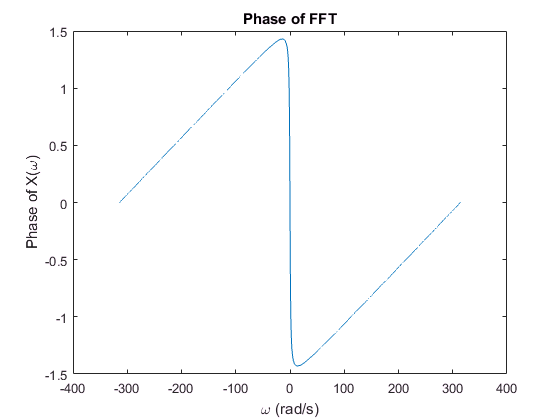


% Plot the phase of FFT
figure;
plot(omega, X_phase);
title('Phase of FFT');
xlabel('\omega (rad/s)');
ylabel('Phase of X(\omega)');

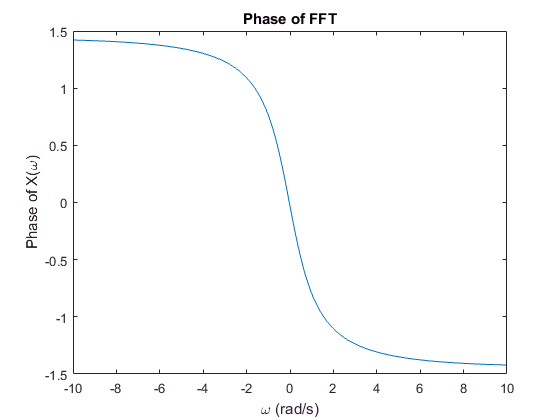

% select omegas in range [-10,10] then plot phase for it!
% make vector form omega and pahse 
phase_vect = [omega;X_phase];
accepted_omegas_idx = find(phase_vect(1,:)>-10&phase_vect(1,:)<10);
accepted_omegas = phase_vect(:,accepted_omegas_idx);
figure;
plot(accepted_omegas(1,:), accepted_omegas(2,:));
title('Phase of FFT');
xlabel('\omega (rad/s)');
ylabel('Phase of X(\omega)');

## discrete time

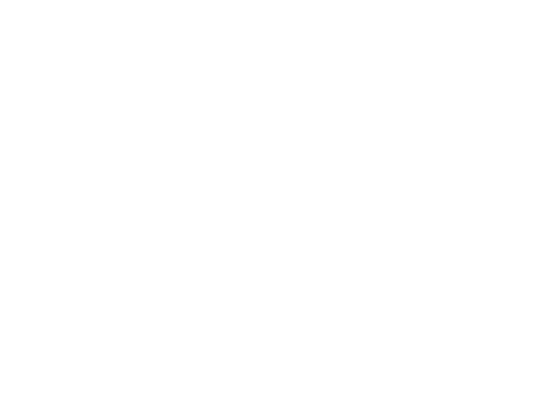

% Define the time vector with sampling period Ts
Ts = 3; % Sampling period in seconds
n = 0:Ts:100; % Time vector

% Define the parameter 'a'
a = 0.9; % Example value

% Define the signal x(t)
x_t = a.^n;
% Plot the signal
figure;
plot(n, x_t);
title('Signal x(t)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;


% Compute the FFT of the signal
X_fft = fft(x_t);

% Compute the number of points in FFT
N = length(X_fft);

% Define the frequency vector for the DFT output
f = (0:N-1)*(1/(Ts*N)); % Frequency vector in Hz

% Shift the zero frequency component to the center and wrap around
f_shifted = mod((f + N/2), N) - N/2; % Shifted and wrapped frequency vector
omega = f_shifted*(2*pi); % Convert to angular frequency in rad/s

% Shift the FFT output
X_fft_shifted = fftshift(X_fft);

% Calculate the magnitude and phase
X_mag = abs(X_fft_shifted);
X_phase = angle(X_fft_shifted);

% Make the magnitude and phase periodic
X_mag = repmat(X_mag, [1, 3]); % Repeat the magnitude vector
X_phase = repmat(X_phase, [1, 3]); % Repeat the phase vector
omega_periodic = (-(3*N)/2:(3*N)/2-1)*(2*pi/(Ts*N)); % Extended omega for periodicity

% Plot the magnitude of FFT
figure;
plot(omega_periodic, X_mag);
title('Magnitude of FFT');
xlabel('\omega (rad/s)');
ylabel('|X(\omega)|');
xlim([-100 100])
ylim([0 200])


% Plot the phase of FFT
figure;
plot(omega_periodic, X_phase);
title('Phase of FFT');
xlabel('\omega (rad/s)');
ylabel('Phase of X(\omega)');

HP and LP filter:

% Define the discrete time vector
n = 0:0.1:100;

% Define the unit step function
u_n = double(n >= 0);

% Define the signal to be filtered
signal = sin(0.1*pi*n) + 0.5*sin(0.5*pi*n); % A sum of two sinusoids

% Low-pass filter (0 < a < 1)
a_low = 0.9;
low_pass_filter = a_low.^n .* u_n;
filtered_signal_low = conv(signal, low_pass_filter, 'same');

% High-pass filter (a > 1)
a_high = -0.9;
high_pass_filter = a_high.^n .* u_n;
filtered_signal_high = conv(signal, high_pass_filter, 'same');

% Plot the original and filtered signals
figure;
subplot(3,1,1);
plot(n, signal);
title('Original Signal');
xlabel('n');
ylabel('Amplitude');

subplot(3,1,2);
plot(n, filtered_signal_low);
title('Low-Pass Filtered Signal');
xlabel('n');
ylabel('Amplitude');

subplot(3,1,3);
plot(n, filtered_signal_high);

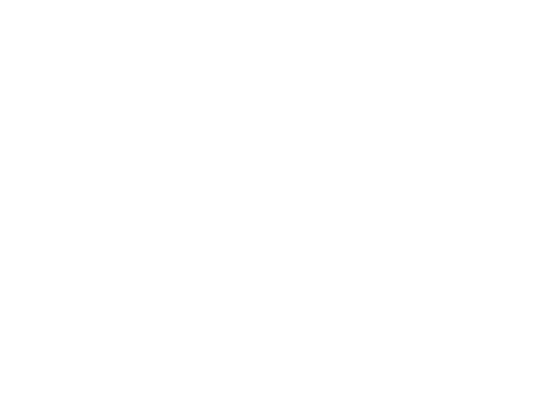

title('High-Pass Filtered Signal');
xlabel('n');
ylabel('Amplitude');

use HP and LP for images

% Load the image
image = imread('peppers.png'); % Replace 'cameraman.tif' with the filename of your image

% Convert the image to grayscale if needed
if size(image, 3) > 1
    image_gray = rgb2gray(image);
else
    image_gray = image;
end

% Define the low-pass and high-pass filters
n = 0:0.1:4;
a_low = 0.001;
a_high = -0.4;
u_n = double(n >= 0);
low_pass_filter_1d = a_low.^n .* u_n;
high_pass_filter_1d = a_high.^n .* u_n;

% Convert the 1D filters to 2D filters
low_pass_filter_2d = low_pass_filter_1d' * low_pass_filter_1d;
high_pass_filter_2d = high_pass_filter_1d' * high_pass_filter_1d;

% Apply the filters to the image
filtered_image_low = conv2(double(image_gray), low_pass_filter_2d, 'same');
filtered_image_high = conv2(double(image_gray), high_pass_filter_2d, 'same');

% Display the original and filtered images
figure;
subplot(3,1,1);
imshow(image_gray);
title('Original Image');

subplot(3,1,2);
imshow(uint8(filtered_image_low));
title('Low-Pass Filtered Image (Blurred Edges)');

subplot(3,1,3);
imshow(uint8(filtered_image_high));

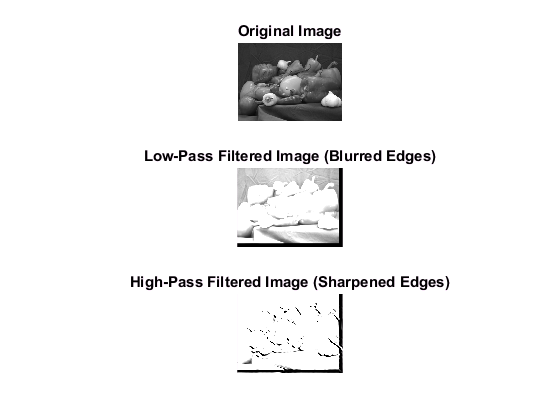

title('High-Pass Filtered Image (Sharpened Edges)');